addpath(genpath('.'));
plotBoundaries = 1.1;

Define lines

coefficients = [3 -0.5 0];
q = [0.2 0.7 0.6];
pointsPerCluster= [300 200 50];

Draw lines

figure
hold on
X = zeros(2, sum(pointsPerCluster));
for i = 1:length(coefficients)
    range = (1 + sum(pointsPerCluster(1:(i - 1)))):(sum(pointsPerCluster(1:i)));
    X(1, range) = (rand(1,pointsPerCluster(i)) - 0.5)*2;
    X(2, range) = coefficients(i) .* X(1, range) + q(i);
end
X(2, :) = X(2, :) / max(X(2, :));
%{
for i = 1:length(coefficients)
    range = (1 + (i-1) * pointsPerCluster(i)):(i * pointsPerCluster(i));
    scatter(X(1,range), X(2,range));
end
%}

Algorithm starts

clusterSize = 10;
clusterThreshold = 25;
labelled_data = false;
numTotPoints = length(X);
nRealPoints = numTotPoints;
nOutliers = 0;
numToClusterizePoints = numTotPoints;    
nClusters = 3;
datasetTitle ="Lines3_15_O0";
%pointsPerCluster = numTotPoints / nClusters;
G = generateGTLbls(nClusters, pointsPerCluster, nOutliers);

    "PtsPerCluster i 1 are 300"

    "PtsPerCluster i 2 are 200"

    "PtsPerCluster i 3 are 50"



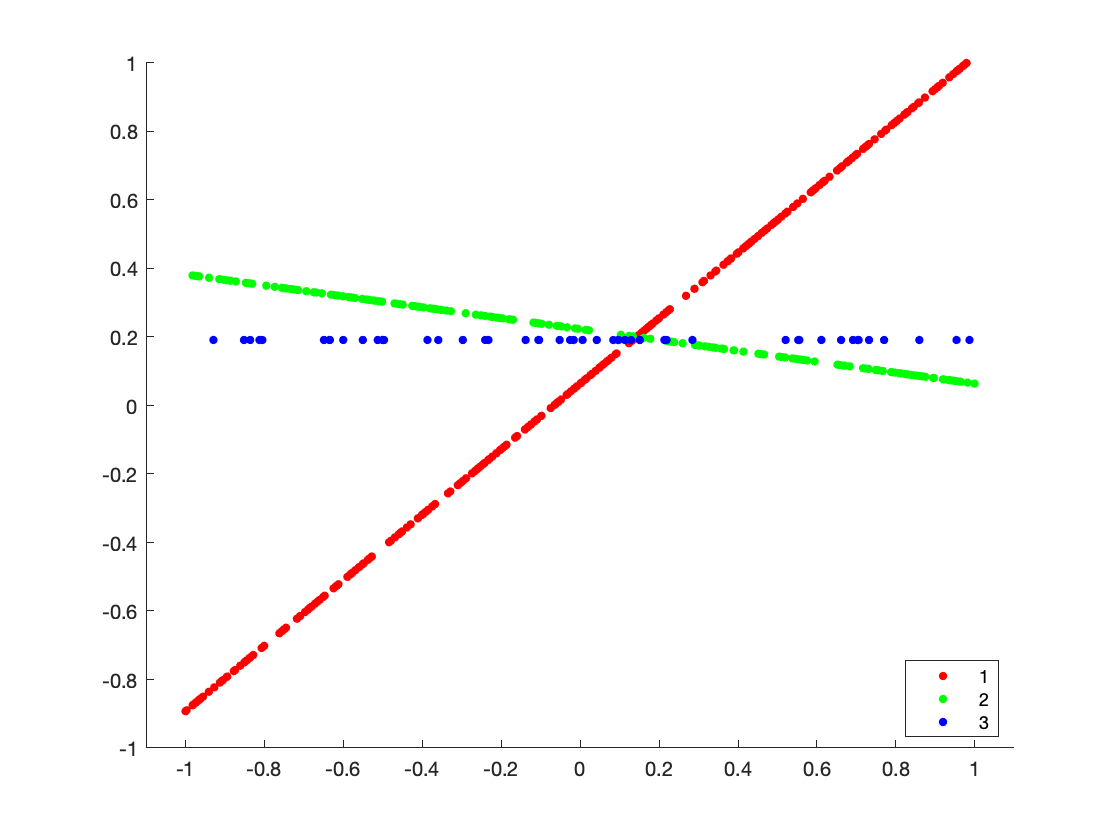

gscatter(X(1,:), X(2,:), G)

[distFun, hpFun, fit_model, cardmss, isMergeableGricModel] = set_model('line');

epsilonRange = 0.12; % An inlier threshold value epsilon has to be specified.

outlierRange = length(X); % consider all points

lambda1 = [];
lambda2 = [];
bestThresholds = [];

epsilon = epsilonRange(1);


%% Perform T-Linkage
[lblsTLinkage, T] = t_linkage(X, distFun, epsilon, cardmss, hpFun);

Now perform dynamic T-Linkage

tree = linkage_to_tree(T);
if length(epsilonRange) == -1
    printBranches(tree, X, max(tree(end,3)));
end

root = tree(end, 3);

lambdaRange = 0:5:60;
[bestLambda1, bestLambda2, bestThreshold] = computeBestParams(root, X, tree, G, lblsTLinkage, lambdaRange, ...
    isMergeableGricModel, epsilon);

    "C found    : "    "2"         
    "Min Res    : "    "1.1652e-06"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "0.082981"  
    "gScore     : "    "0.50027"   

    "C/Gscore : "    "0.5 vs. 0.082981"

    "C found    : "    "2"        
    "Min Res    : "    "0.0013859"
    "Complexity : "    "0.5"      
    "Fidelity   : "    "1"        
    "gScore     : "    "0.50403"  

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "1"       
    "Min Res    : "    "0.085246"
    "Complexity : "    "2"       
    "Fidelity   : "    "1"       
    "gScore     : "    "2.0018"  

    "C/Gscore : "    "2 vs. 1"

    "Clusters found so far "    "2"

    "Fidelity Before : "      "1.083"
    "Fidelity After : "       "1"    
    "Complexity Before : "    "1"    
    "Complexity After : "     "2"    

    "2.0018"    " <= "    "1.0043"    " ?"

    "C found    : "    "3"         
    "Min Res    : "    "3.0177e-08"
    "Complexity : "    "0"         
    "Fidelity   : "    

    "C found    : "    "2"         
    "Min Res    : "    "1.1652e-06"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "0.082981"  
    "gScore     : "    "0.50027"   

    "C/Gscore : "    "0.5 vs. 0.082981"

    "C found    : "    "2"        
    "Min Res    : "    "0.0013859"
    "Complexity : "    "0.5"      
    "Fidelity   : "    "1"        
    "gScore     : "    "0.50403"  

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "1"       
    "Min Res    : "    "0.085246"
    "Complexity : "    "2"       
    "Fidelity   : "    "1"       
    "gScore     : "    "2.0018"  

    "C/Gscore : "    "2 vs. 1"

    "Clusters found so far "    "2"



    "Fidelity Before : "      "1.083"
    "Fidelity After : "       "1"    
    "Complexity Before : "    "1"    
    "Complexity After : "     "2"    

    "2.0018"    " <= "    "1.0043"    " ?"

    "C found    : "    "3"         
    "Min Res    : "    "3.0177e-08"
    "Complexity : "    "0"         
    "Fidelity   : "    "1"         
    "gScore     : "    "0.0033113" 

    "C/Gscore : "    "0 vs. 1"

    "C found    : "    "3"         
    "Min Res    : "    "7.7037e-34"
    "Complexity : "    "0"         
    "Fidelity   : "    "1"         
    "gScore     : "    "0.33333"   

    "C/Gscore : "    "0 vs. 1"

    "C found    : "    "2"         
    "Min Res    : "    "1.1652e-06"
    "Complexity : "    "1"         
    "Fidelity   : "    "1"         
    "gScore     : "    "1.0033"    

    "C/Gscore : "    "1 vs. 1"

    "Clusters found so far "    "3"



    "Fidelity Before : "      "2"
    "Fidelity After : "       "1"
    "Complexity Before : "    "0"
    "Complexity After : "     "1"

    "1.0033"    " <= "    "0.33664"    " ?"

    "C found    : "    "4"         
    "Min Res    : "    "3.9774e-33"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "0.50559"   
    "gScore     : "    "0.50174"   

    "C/Gscore : "    "0.5 vs. 0.50559"

    "C found    : "    "4"         
    "Min Res    : "    "6.8942e-07"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "1"         
    "gScore     : "    "0.58333"   

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "3"         
    "Min Res    : "    "3.0177e-08"
    "Complexity : "    "0"         
    "Fidelity   : "    "1"         
    "gScore     : "    "0.0033113" 

    "C/Gscore : "    "0 vs. 1"

    "Clusters found so far "    "3"



    "Fidelity Before : "      "1.5056"
    "Fidelity After : "       "1"     
    "Complexity Before : "    "1"     
    "Complexity After : "     "0"     

    "0.0033113"    " <= "    "1.0851"    " ?"

    "C found    : "    "4"  
    "Min Res    : "    "100"
    "Complexity : "    "0.5"
    "Fidelity   : "    "1"  
    "gScore     : "    "1"  

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "4"  
    "Min Res    : "    "100"
    "Complexity : "    "0.5"
    "Fidelity   : "    "1"  
    "gScore     : "    "1"  

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "3"         
    "Min Res    : "    "7.7037e-34"
    "Complexity : "    "0"         
    "Fidelity   : "    "1"         
    "gScore     : "    "0.33333"   

    "C/Gscore : "    "0 vs. 1"

    "Clusters found so far "    "3"



    "Fidelity Before : "      "2"
    "Fidelity After : "       "1"
    "Complexity Before : "    "1"
    "Complexity After : "     "0"

    "0.33333"    " <= "    "2"    " ?"

    "C found    : "    "4"         
    "Min Res    : "    "9.2726e-07"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "1"         
    "gScore     : "    "0.5049"    

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "4"         
    "Min Res    : "    "7.7037e-34"
    "Complexity : "    "0.5"       
    "Fidelity   : "    "1"         
    "gScore     : "    "0.52222"   

    "C/Gscore : "    "0.5 vs. 1"

    "C found    : "    "3"        
    "Min Res    : "    "0.0013859"
    "Complexity : "    "0"        
    "Fidelity   : "    "1"        
    "gScore     : "    "0.0040323"

    "C/Gscore : "    "0 vs. 1"

    "Clusters found so far "    "3"



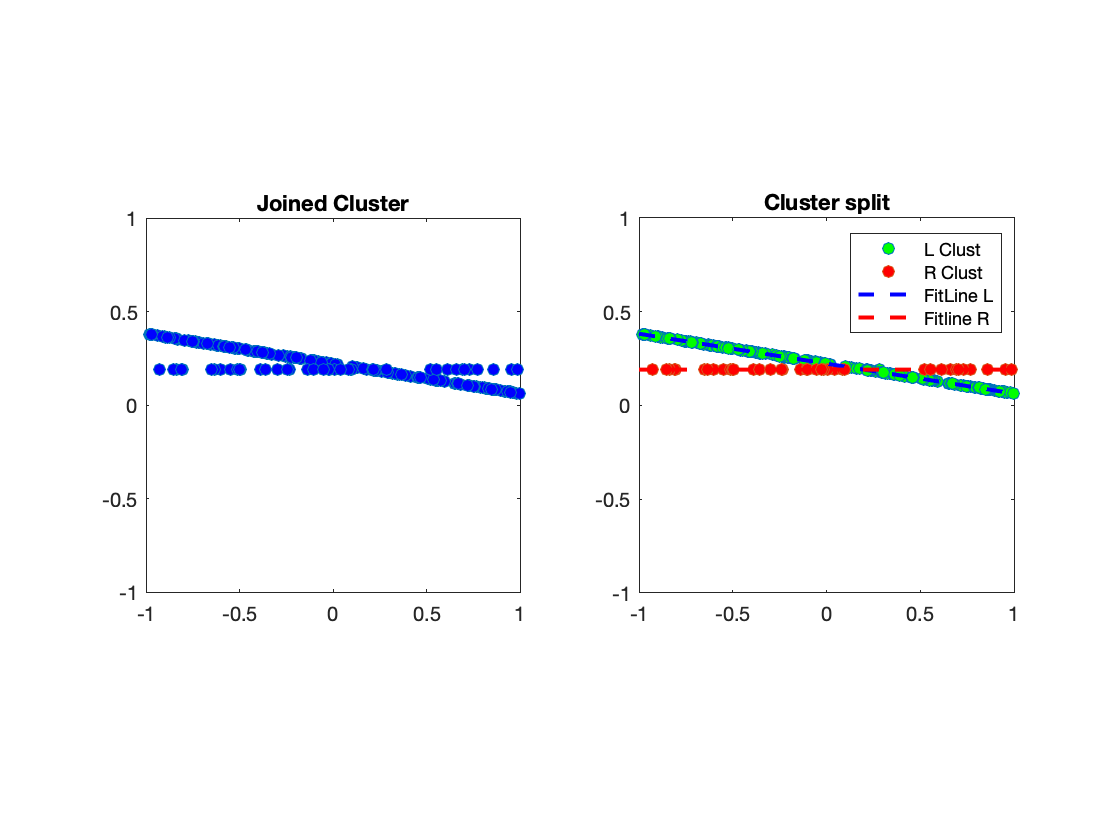

    "Fidelity Before : "      "2"
    "Fidelity After : "       "1"
    "Complexity Before : "    "1"
    "Complexity After : "     "0"

    "0.0040323"    " <= "    "1.0271"    " ?"




%%
[~, ~, ~, ~, toMergeClusters] = exploreDFS(root, X, tree, bestLambda1, bestLambda2, epsilon, ...
    isMergeableGricModel, true);

lblsDynTLinkage = labelsAfterDynCut(X, tree, toMergeClusters, bestThreshold);

Dynamic T-Linkage ended, now perform improvement of what dyn T-Linkage provides

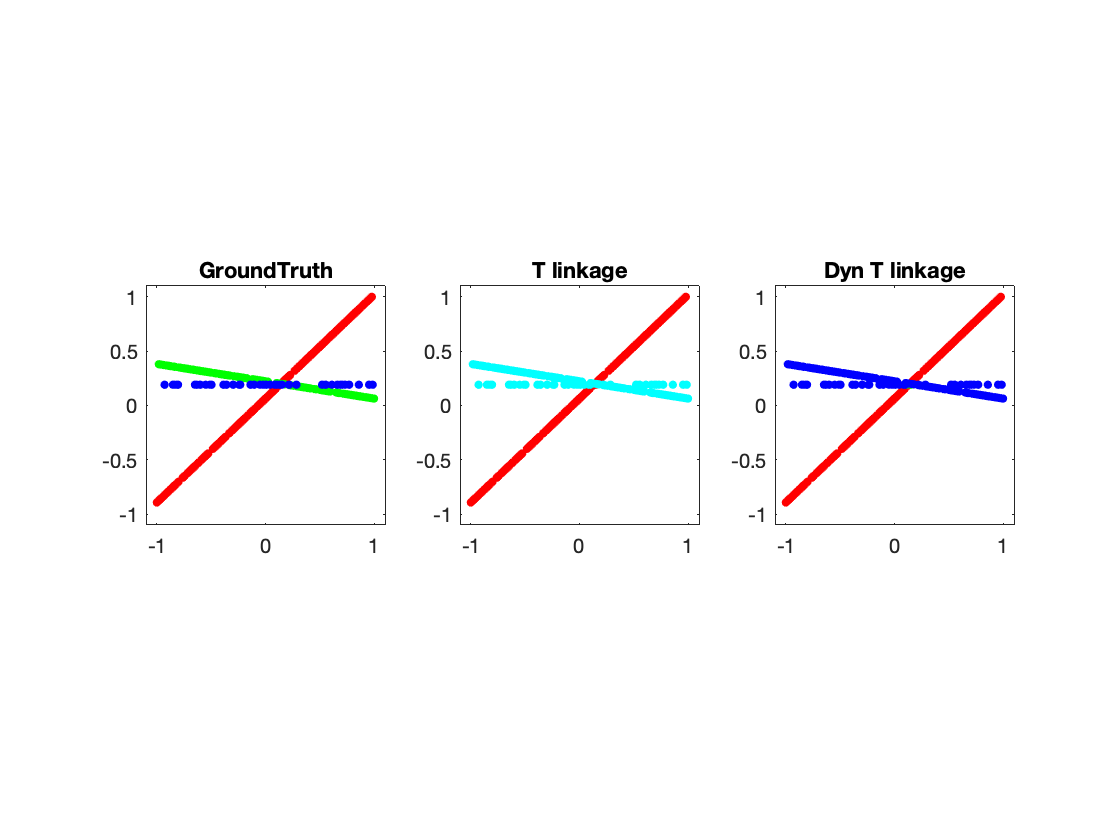


lambda1(end + 1) = bestLambda1;
lambda2(end + 1) = bestLambda2;
bestThresholds(end + 1) = bestThreshold;

%% Outlier rejection step

%T-Linkage fit a model to all the data points. Outlier can be found in
%different ways (T-Linkage is agonostic about the outlier rejection strategy),
%for example discarding too small cluster, or exploiting the randomness of
%a model.

lblsTLinkage = operateOnOutliers(lblsTLinkage, cardmss);
%lblsDynTLinkage = operateOnOutliers(lblsDynTLinkage, cardmss);


%% Order labels step
lblsTLinkage = orderClusterLabels(lblsTLinkage, pointsPerCluster);
lblsDynTLinkage = orderClusterLabels(lblsDynTLinkage, pointsPerCluster);

candidateOutliers = LOF(X');
lblsLOFDynCut = lblsDynTLinkage;
lblsLOFDynCut(candidateOutliers) = 0;

%% Showing results
if length(epsilonRange) == 1 && length(outlierRange) == 1
    figure('name','Assigned labels')
    s = subplot(1,3,1); gscatter(X(1,:),X(2,:), G); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('GroundTruth'); legend off
    s = subplot(1,3,2); gscatter(X(1,:),X(2,:), lblsTLinkage); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('T linkage'); legend off
    s = subplot(1,3,3); gscatter(X(1,:),X(2,:), lblsDynTLinkage); axis(s, 'equal'); xlim(s, [-plotBoundaries plotBoundaries]); ylim(s, [-plotBoundaries plotBoundaries]); title('Dyn T linkage'); legend off
end

Here we do some comparison to ground truth, to compare the outcomes changing parameters

%% Compare clustering
tLinkageMetrics = compareClustering(G, lblsTLinkage);
dynTLinkageMetrics = compareClustering(G, lblsDynTLinkage);
%LOFdynTLinkageMetrics = compareClustering(G, lblsLOFDynCut);

%metrics(outlierIdx, eps).tLinkage = tLinkageMetrics;
%metrics(outlierIdx, eps).dynTLinkage = dynTLinkageMetrics;